# Linear Control Design II - Group Work Problem Module 18

## Description

**Problem 1** Consider the $2^{\mathrm{nd}}$ order SISO system


$$\dot{\mathbf{x}}=\mathbf{A}\mathbf{x} + \mathbf{B}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rr}
  -1 & 1\\
  0 & 2
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  1\\
  0
 \end{array}\right]$$


The optimal control law 


$$u = -\mathbf{K}\mathbf{x}$$


is to be designed by minimizing the performance index $J$ given by:


$$J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


Where:


$$ \mathbf{R}_1 = \left[
 \begin{array}{rr}
  1 & 0\\
  0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  1  
 \end{array}\right]$$


- Show analytically that the system cannot be stabilized by any gain matrix $\mathbf{K}$.

- Draw a block diagram of the system and use it to explain your results.

- Use the Matlab function `lqr` to design the optimal controller. Discuss the numerical results in relation to your analytical findings.

**Solution****:**

% Your solution goes here:
A = [-1 1;
      0 2];
B = [1;0];
Kc =  ctrb(A,B)

Kc =      1    -1
     0     0


if rank(Kc)<ndims(A)
    disp('system is not controllable')
else
    disp('sys is controllable')
end

system is not controllable


R1 = [1 0;0 1];
R2 = 1

R2 =      1


% K = lqr(A,B,R1,R2)

**Problem 2**  Consider the $2^{\mathrm{nd}}$ order SISO system


$$ \dot{\mathbf{x}}=\mathbf{A}\mathbf{x} + \mathbf{B}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rr}
  0 & 1\\
  0 & -1
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  0\\
  1
 \end{array}\right]
$$


The optimal control law 


$$u = -\mathbf{K}\mathbf{x}$$


is to be designed by minimizing the performance index $J$ given by:


$$J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


where:


$$\mathbf{R}_1 = \left[
 \begin{array}{rr}
  1 & 0\\
  0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  1  
 \end{array}\right]$$


- Determine the optimal feedback gain matrix **K** for this system.

**Solution****:**

% system matrix
A = [0 1;0 -1];
B = [0;1];
C = [1 1];
D = 0;
% assess controllability
Mc = ctrb(A,B);
if rank(Mc)<ndims(A)
    disp('system is not controllable')
else
    disp('sys is controllable')
end

sys is controllable


% weighting matrices
R1 = [1 0;0 1];
R2 = 1;

% optimal control gain
[K,P,E] = lqr(A,B,R1,R2);
disp(K)

            1            1



disp('Solution of algebraic Riccati equation')

Solution of algebraic Riccati equation


disp(P)

            2            1
            1            1



disp('Closed loop eigenvalues')

Closed loop eigenvalues


disp(E)

           -1
           -1



So the solution is:


$$P = \left[\matrix{2 \ 1 \cr 1 \ 1}\right]$$



$$K = R_2^{-1}B^TP =[1][0 \ 1]\left[\matrix{2 \ 1 \cr 1 \ 1}\right]=[1 \ 1]$$



$$u =-Kx=-x_1-x_2$$


Ak = A-B*K;
k1 = K(1)

k1 =             1


k2 = K(2)

k2 =             1


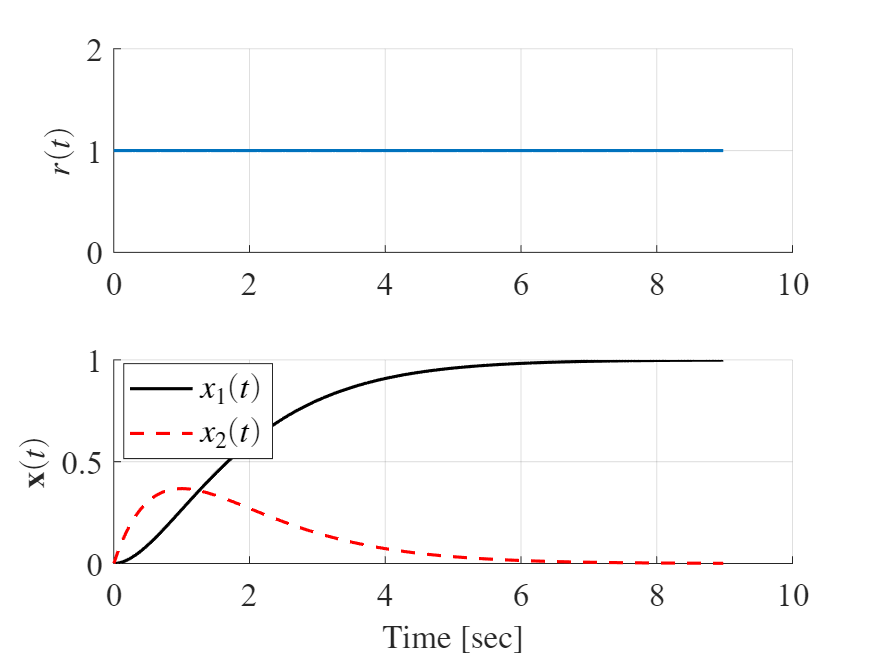

Bk = B*k2;
[y,x,t] = step(Ak,Bk,C,D);
figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
u = square(2*pi*0.05*t);
plot(t,u,'LineWidth',1.5);
ylabel('$r(t)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,[1 0]*x','-k',t,[0 1]*x','--r','LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'Interpreter','latex')
l = legend('$x_1(t)$','$x_2(t)$','Location','Best');
set(l,'FontName','times','FontSize',16,'Interpreter','latex');

**Problem 3**  Consider the $3^{\mathrm{rd}}$ order SISO system


$$\dot{\mathbf{x}} =\mathbf{A}\mathbf{x} + \mathbf{B}u\\
 y = \mathbf{C}\mathbf{x} + \mathbf{D}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rrr}
  0 & 1 & 0\\
  0 & 0 & 1\\
  0 & -2 & -3
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  0\\
  0\\
  1
 \end{array}\right]
 \qquad
 \mathbf{C} = \left[
 \begin{array}{rrr}
  1 & 0 & 0
 \end{array}\right]
 \qquad
 \mathbf{D} = \left[
 \begin{array}{r}
  0
 \end{array}\right]$$


The performance index $J$ is given by:


$$ J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


where:


$$\mathbf{R}_1 = \left[
 \begin{array}{rrr}
  100 & 0 & 0\\
  0 & 1 & 0\\
  0 & 0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  0.01  
 \end{array}\right]$$


- Why would one choose the matrix elements of the state weighting matrix in this way?

  Assume that the following control law is designed


$$u=k_1(r-x_1) - (k_2x_2+k_3x_3)$$


where $r$ is the reference input to the system.

        2. What control objective is fulfilled with the given feedback law?

        3. Determine the optimal steady state feedback gain matrix $\mathbf{K}$ for this system.

        4. Plot the step response of the closed loop system.

**Solution****:**

- Restrictions on state error is more than that on the size of control input. Also, the main control object is x1. Choose weighting number as 100 makes x1 a faster response

% system matrix
A = [0 1 0; 0 0 1;0 -2 -3];
B = [0;0;1];
C = [1 0 0];
D = 0;

% assess controllability
Mc = ctrb(A,B);
if rank(Mc)<ndims(A)
    disp('system is not controllable')
else
    disp('sys is controllable')
end

sys is controllable



% weightging matrices
R1 = [100 0 0;0 1 0;0 0 1];
R2 = 0.01;

% optimal control
[K,P,E] = lqr(A,B,R1,R2);
disp('Optimal gain matrix')

Optimal gain matrix


disp(K)

          100        53.12       11.671



disp('Solution of algebric Riccati equation')

Solution of algebric Riccati equation


disp(P)

        55.12       14.671            1
       14.671       7.0267       0.5312
            1       0.5312      0.11671



disp('Closed loop eigenvalues')

Closed loop eigenvalues


disp(E)

      -2.2141 +     2.2047i
      -2.2141 -     2.2047i
      -10.243 +          0i



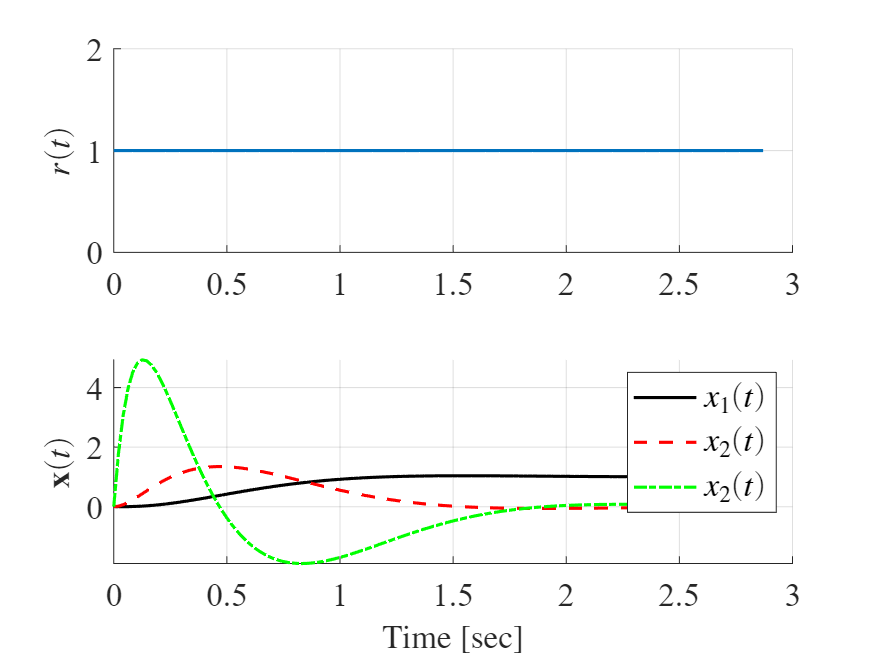

Ak = A - B*K;
Bk = B*K(1);
[y,x,t] = step(Ak,Bk,C,D);
figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
u = square(2*pi*0.05*t);
plot(t,u,'LineWidth',1.5);
ylabel('$r(t)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,[1 0 0]*x','-k',t,[0 1 0]*x','--r',t,[0 0 1]*x','-.g','LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'Interpreter','latex')
l = legend('$x_1(t)$','$x_2(t)$','$x_2(t)$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'Interpreter','latex');